# FRA 333 : Kinematics of Robotics System

 **NAME**              : 3D Robot Programming (Option 1)

 **AUTHOR**         :  Kantaka Sirithanarattanakul     62340500002

                            Keedita   Chaihetphon              62340500003

                            Pakapak  Silpapinun                 62340500042

                            Jompon   Petaibanlue               62340500060

 **DATE**               : December 12th 2021

** DESCRIPTION**    : To develop a position control program for a 3 DOF serial manipulator robot that moves in 3D using a quintic polynomial and is viewed using voxel-based planning.

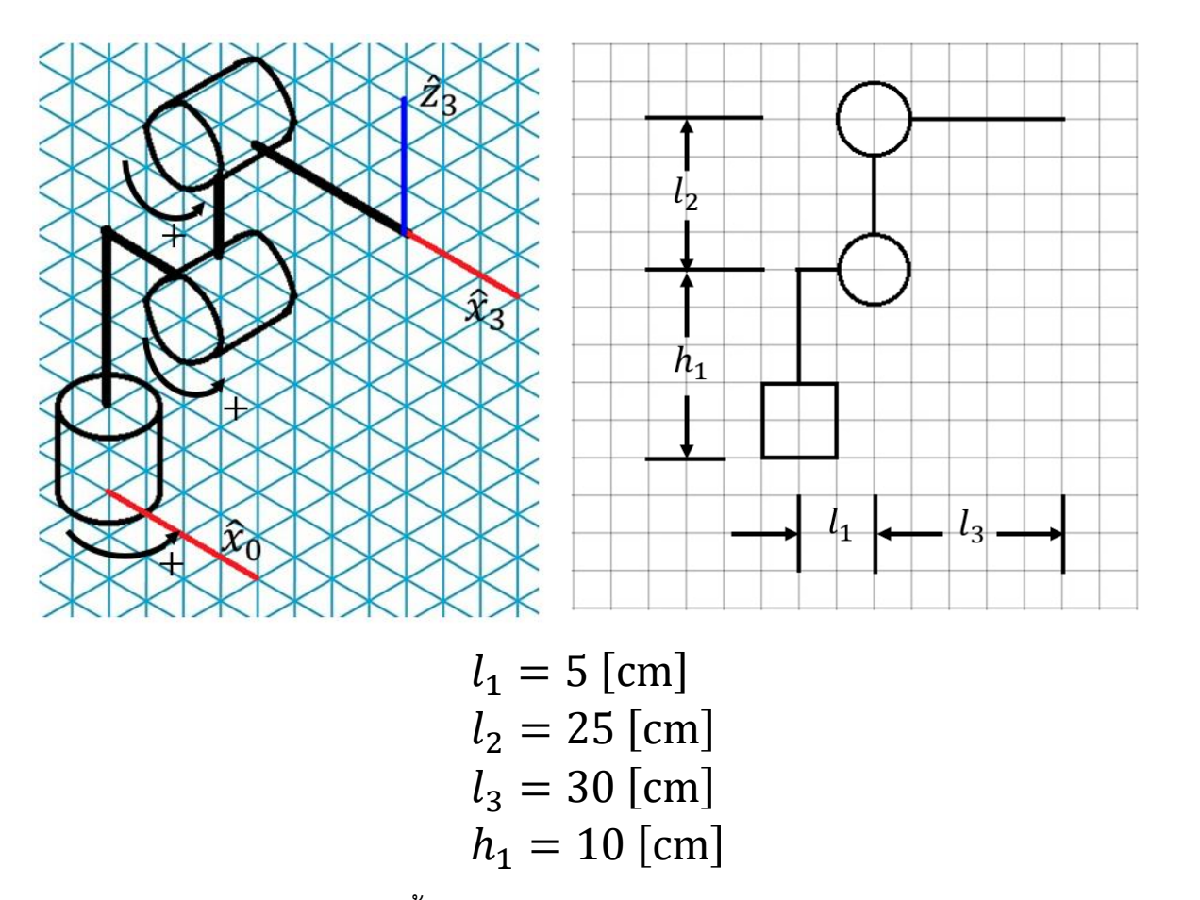             

#### **Conditions and requirements**

- The information of via-points is stated of p1,p2,p3,p4 as (10, 20, 5) (10, 15, 5) (15, 15, 2) (17.5, 17.5, 0) which is saved as "via point info.txt" and the user commands the robot using format **(movement, position)** which is saved as "robot command.txt" for example: (J, p1) (J, p2) (J, p3) (L, p3) (J, p1)

- The term "**movement**" refers to a linear movement in Joint-space (J) or Task-space (L) 

- The robot must have a zero ending velocity when it reaches each of the via-points

- The robot must have a zero ending acceleration when it reaches each of the via-points

- Within the constraints, the robot must choose the optimal path.

- When a command causes singularity, the robot must send an alert.

- Every value in the txt file is given in SI units.

- The following are the robot's parameters : L1 = 5 cm, L2 = 25 cm, L3 = 30 cm, h1 = 10 cm

- The user can set the maximum velocity and acceleration of each robot's joint.

- Assume that the system is free of external forces and friction.

#### **Workflow of the system            **              

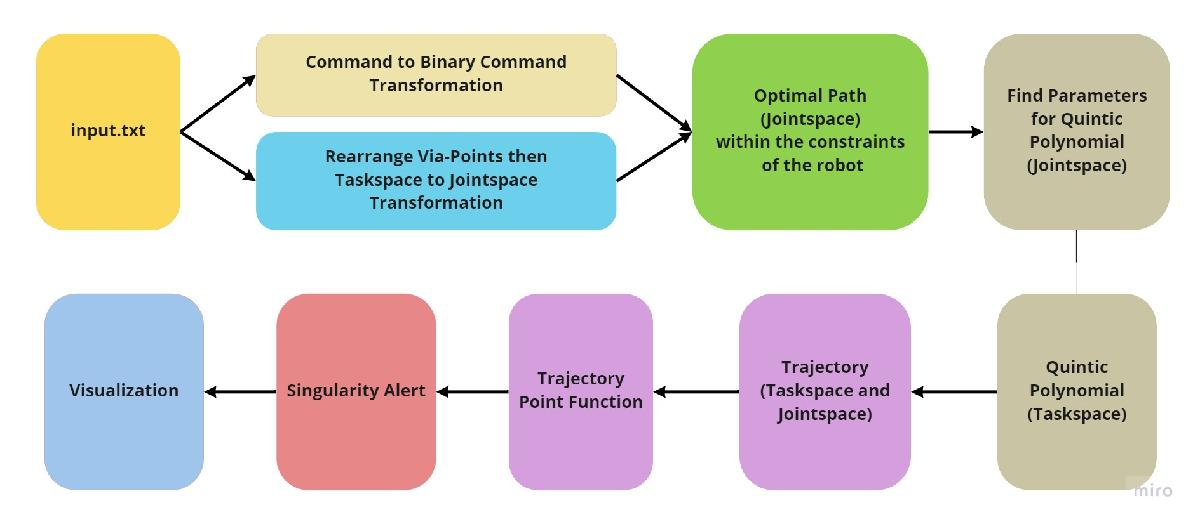           

### System Descriptions

**Coordinate Frames **at home configuration         

#### 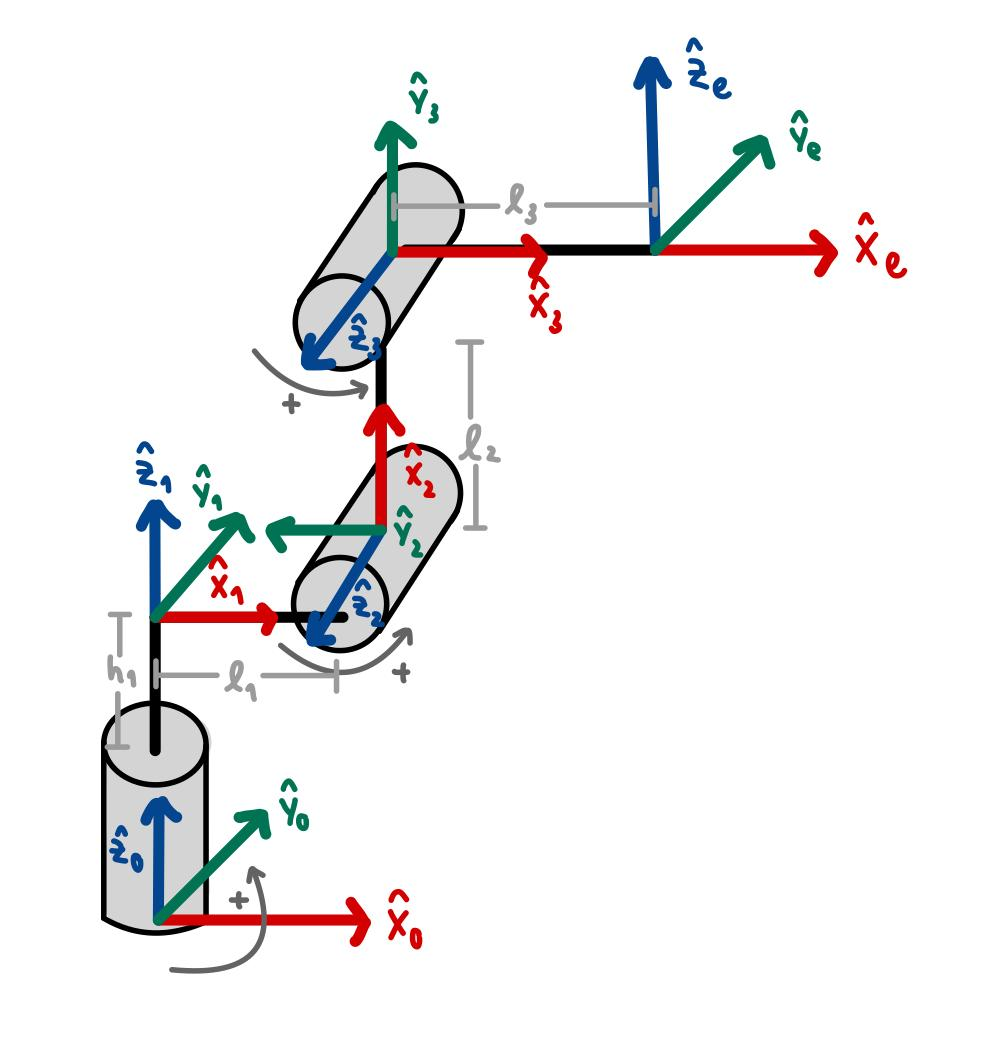               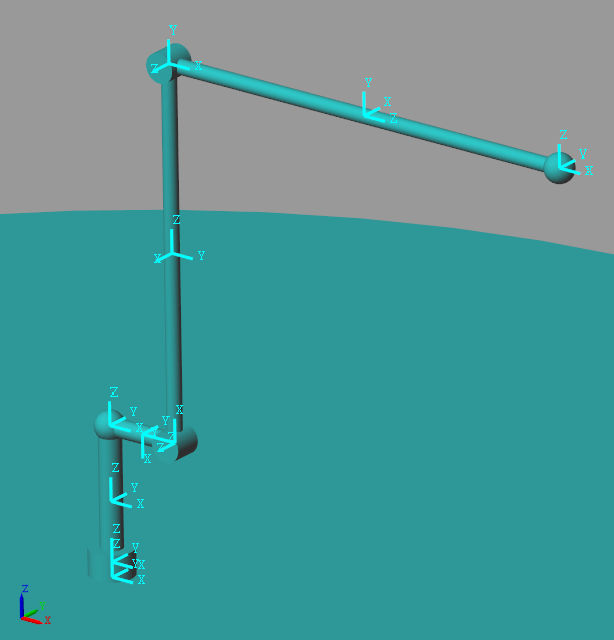

**Kinematics Model/Parameters**

L1 = 0.05;        % Length of Link 1 [m]
L2 = 0.25;        % Length of Link 2 [m]
L3 = 0.30;        % Length of Link 3 [m]
h1 = 0.10;        % Length of Height [m]

row1 = [0;1;2];                             % DH Table
row2 = [1;2;3];                             %   i-1     i       a_i      alpha_i     d_i     theta_i  
linklength = [0;L1;0];                      %    0      1        0         0         h1        0                 
linktwist = [0;pi/2;pi/2];                  %    1      2       L1        pi/2       0        pi/2
linkoffset = [h1;0;L2];                     %    2      3       L2         0         0       -pi/2
jointoffset = [0;pi/2;0];
varNames = ["i-1","i","a_i","alpha_i","d_i","theta_i"];
DHTable = table(row1,row2,linklength,linkoffset,linktwist,jointoffset,'VariableNames',varNames)  %DH Table

DHTable = 3×6 table
    i-1    i    a_i     alpha_i     d_i      theta_i
    ___    _    ____    _______    ______    _______

     0     1       0      0.1           0         0 
     1     2    0.05        0      1.5708    1.5708 
     2     3       0     0.25      1.5708         0 


Homogeneous Transformation of last link (L3) respect to ene-effector (e) :

 
$$H_e^3 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & \mathrm{L3}\\
0 & 0 & 1 & 0\\
0 & -1 & 0 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$
                                                                                                                                          

**Input**

    .txt:    robot command = (2,n)  // consists of  (movement, position)

    .txt:    via_point_info = (3,m) // m = size of command via_points_task set in task space

**Local variables**

    command = (1,n) L:0,J:1 

    via_point_task = (3,n) 

    via_point_joint_all = (3,n,4)

    via_point_joint = (3,n)

### Methodology 

**Step 1 : readVariable **write .txt + return: via_point_task = (3,n), command = (1,n) L:0,J:1 

      Description: read variables

via_point_task ($\overrightarrow{\mathbf{P}}$)     : $\Re^{\mathrm{N}\times \mathrm{M}}$ which $\mathbf{N}$ is cartesian dimensions and $\mathbf{M}$ is number of via-point

command ($\overrightarrow{\mathbf{A}}$)            : $\overrightarrow{\mathbf{A}} \in {\left\lbrace 0,1\right\rbrace }^{1\times \mathrm{M}}$ which $\mathbf{M}$ is number of via-point ("**0**" means mode L operation and "**1**" means mode J operation)


$$\overrightarrow{\mathbf{P}} =\left\lbrack \begin{array}{cccc}
\overrightarrow{p_1 }  & \overrightarrow{p_2 }  & \overrightarrow{p_3 }  & \cdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
p_{x_1 }  & p_{x_2 }  & p_{x_3 }  & \cdots \\
p_{y_1 }  & p_{y_2 }  & p_{y_3 }  & \cdots \\
p_{z_1 }  & p_{z_2 }  & p_{z_3 }  & \cdots 
\end{array}\right\rbrack$$


[command, via_point_task] = readVariable("robot_command_v0.txt", "via_points_info_v0.txt")

command =      1     1     1     0


via_point_task =     0.3500    0.5962    0.2621   -0.2621
         0         0         0         0
    0.3500    0.1434    0.5621    0.5621


**Step 2 : task2jointConversion** return alert 0: cant access, 1: accessable

 via_point_joint (3x4xn) which D2 is possible joint and D3 is No. input via_point task

      Description: check possible access + convert taskspace to jointspace (via_point)

via_point_joint       : $\Re^{\mathrm{K}\times \mathrm{S}\times \mathrm{M}}$ which $\mathbf{K}$ is number of joint, $\mathbf{S}$ is number of robot pose and $\mathbf{M}$ is number of via-point

[alert, via_point_joint] = task2jointConversion(via_point_task);
via_point_joint(:,:,1) = zeros(3,4);
via_point_joint

via_point_joint = via_point_joint(:,:,1) =

     0     0     0     0
     0     0     0     0
     0     0     0     0


via_point_joint(:,:,2) =

         0         0   99.0000   99.0000
   -1.5867   -1.3963   99.0000   99.0000
    1.7453    1.3963   99.0000   99.0000


via_point_joint(:,:,3) =

         0         0   99.0000   99.0000
   -0.8607         0   99.0000   99.0000
    2.3562    0.7854   99.0000   99.0000


via_point_joint(:,:,4) =

    3.1416    3.1416   99.0000   99.0000
   -0.8607         0   99.0000   99.0000
    2.3562    0.7854   99.0000   99.0000


alert

alert =      1     1     1     1


**Step 3 : optimalPath **return selected_via_point_joint (3xn)

      Description: select the robot pose that took shortest path cost

selected_via_point_joint ($\overrightarrow{\mathbf{Q}}$)    : $\Re^{\mathrm{K}\times \mathrm{M}}$ which $\mathbf{K}$ is number of joint and $\mathbf{M}$ is number of via-point


$$\overrightarrow{\mathbf{Q}} =\left\lbrack \begin{array}{cccc}
\overrightarrow{q_1 }  & \overrightarrow{q_2 }  & \overrightarrow{q_3 }  & \cdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
q_{1_1 }  & q_{1_2 }  & q_{1_3 }  & \cdots \\
q_{2_1 }  & q_{2_2 }  & q_{2_3 }  & \cdots \\
q_{3_1 }  & q_{3_2 }  & q_{3_3 }  & \cdots 
\end{array}\right\rbrack$$


[selected_via_point_joint, all_via_point_joint, cost] = optimalPath(via_point_joint, "shortest_path");

min_cost = 5.4978

min_idx = 5

selected_via_point_joint

selected_via_point_joint =          0         0         0    3.1416
         0   -1.3963   -0.8607   -0.8607
         0    1.3963    2.3562    2.3562


**Step 4 : coefficientGen **return set of C, t_i, and tau

      Description: return for quintic polynomial coefficients and via-point time stamp (in configuration space)

$\overrightarrow{\mathbf{C}}$    : $\Re^{\mathrm{N}\times \mathrm{U}\times \left(\mathrm{M}-1\right)}$ which $\mathbf{N}$ is cartesian dimensions, $\mathbf{U}$ is quintic polynomial coefficients and $\mathbf{M}$ is number of via-point


$$\overrightarrow{\mathbf{C}} =\left\lbrack \begin{array}{cccccc}
{\overrightarrow{{\mathit{\mathbf{c}}}_0 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_1 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_2 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_3 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_4 } }_{\textrm{q1}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_5 } }_{\textrm{q1}} \\
{\overrightarrow{{\mathit{\mathbf{c}}}_0 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_1 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_2 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_3 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_4 } }_{\textrm{q2}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_5 } }_{\textrm{q2}} \\
{\overrightarrow{{\mathit{\mathbf{c}}}_0 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_1 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_2 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_3 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_4 } }_{\textrm{q3}}  & {\overrightarrow{{\mathit{\mathbf{c}}}_5 } }_{\textrm{q3}} 
\end{array}\right\rbrack$$


$\overrightarrow{{\mathit{\mathbf{t}}}_i }$(via-point time stamp)    : $\Re^{1\times \left(\mathrm{M}-1\right)}$ which $\mathbf{M}$ is number of via-point

%Setting maximum velocity and acceleration of each joint
v_max = 1.75;
a_max = 0.5;

[C,t_i,T,alert_traj] = coefficientGen(selected_via_point_joint, v_max, a_max)

C = C(:,:,1) =

         0         0         0         0         0         0
         0         0         0   -0.2157    0.0806   -0.0080
         0         0         0    0.2157   -0.0806    0.0080


C(:,:,2) =

         0         0         0         0         0         0
   -1.3963         0         0    0.1451   -0.0654    0.0079
    1.3963         0         0    0.2601   -0.1172    0.0141


C(:,:,3) =

         0         0         0    0.1438   -0.0358    0.0024
   -0.8607         0         0         0         0         0
    2.3562         0         0         0         0         0


t_i =          0    4.0153    7.3446


T = 13.3676

alert_traj = 0

**Step 5 : **

      Description: return for quintic polynomial coefficients and via-point time stamp (in task space)

**Step 6 : polyTrajEval **return set of p1, v1, a1

      Description: return the position, velocity and acceleration in configuration space

sampling = 1e-2; t = (0:sampling:T); %linspace(0,T,100+1);
p1 = [];
v1 = [];
a1 = [];

for i = 1:numel(t)
    k = discretize(t(i),[t_i T]);
   [p_j,v_j,a_j] = polyTrajEval(t(i),C(:,:,k),t_i(k));

    p1 = [p1 p_j];
    v1 = [v1 v_j];
    a1 = [a1 a_j];

end

[R,P,R_e,p_e] = forwardKine(p1);

p2 = p_e;
v2 = [zeros(3,1) diff(p2')'];
a2 = [zeros(3,1) diff(v2')'];

**Step 7 : plotTrajectory **(void)

      Description: visualization the plot of position, velocity and acceleration with respect to time in configuration and task space

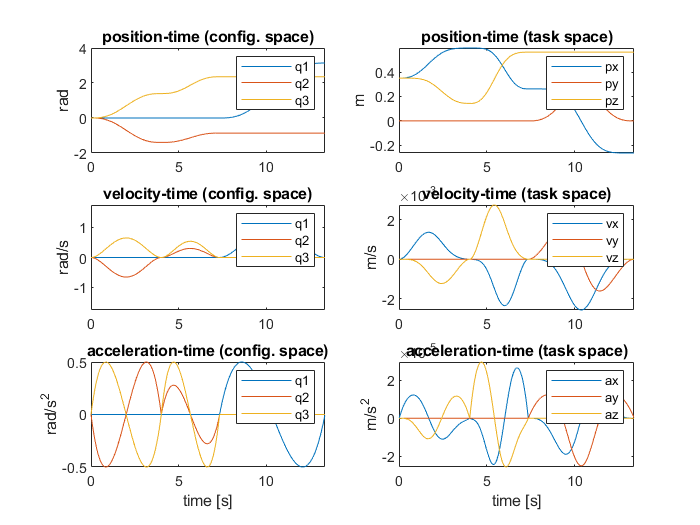

plotTrajectory(t, p1,v1,a1, p2,v2,a2, T, v_max,a_max)          

**Step 8 : checkSingularity **return alert_singularity, idx, border and J_v

[alert_singularity, idx, border,J_v] = checkSingularity(p1, t);
alert_singularity

alert_singularity = 0

**Step 9 : Visualization**

### Implementation & Results

- The robot must follow the commands given to it.

- The robot must have a zero ending velocity and acceleration when it reaches each of the via-points

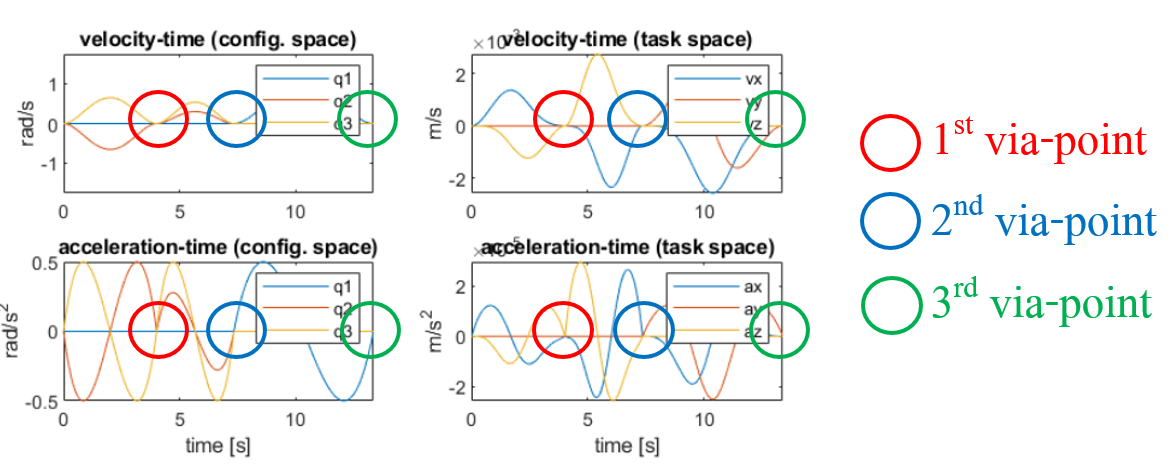

    The velocity-time and acceleration-time graphs in configuration space and time space that have been plotted by the order to go to 3 via-points (red : 1st via-point, blue : 2nd via-points, green : 3rd via-points) are shown above. The velocity and acceleration equal zero at the end of each via-points. 

- Within the constraints, the robot must choose the optimal path.

- When a command causes singularity, the robot must send an alert.

- The user can set the maximum velocity and acceleration of each robot's joint. 

        

 By adjusting these 2 variables, the user can set the maximum velocity and acceleration of the robot's joints: **v_max **and **a_max**.

### **Conclusion**

    In the conclusion, the given task, programing a 3DOF serial manipulator robot in voxel-based planning with quintic polynomial trajectory, is accomplished under the given conditions and requirements. To complete the goal, the knowledge from FRA333, forward kinematic and inverse kinematic, is applied and used to identify the pose, velocity, acceleration of the robot. However, in some particular point, the robot may lose its degree of freedom. To prevent the singularity occurred in the trajectory, the jacobian matrix is identified.  Finally, to observe the created program, the robot is simulate in SIMULINK.